%encoding functions
function y = mul_sh(x, k)
    if k == -1
        y = zeros(1, length(x));
    else
        y = [x(k+1:end) x(1:k)];
    end
end

function [B,H,z] = nrldpc_Hmatrix(BG)
    load(sprintf('%s.txt',BG),BG);
    B = NR_2_6_52;
    [mb,nb] = size(B);
    z = 52;
    H = zeros(mb*z,nb*z); 
    Iz = eye(z); I0 = zeros(z);
    for kk = 1:mb
        tmpvecR = (kk-1)*z+(1:z);
        for kk1 = 1:nb
            tmpvecC = (kk1-1)*z+(1:z);
            if B(kk,kk1) == -1
                H(tmpvecR,tmpvecC) = I0;
            else
                H(tmpvecR,tmpvecC) = circshift(Iz,-B(kk,kk1));
            end
        end
    end
    
    [U,N]=size(H); K = N-U;
    P = H(:,1:K);
    G = [eye(K); P];
    Z = H*G;
end

function cword = nrldpc_encode(B,z,msg)
    %B: base matrix
    %z: expansion factor
    %msg: message vector, length = (#cols(B)-#rows(B))*z
    %cword: codeword vector, length = #cols(B)*z
    
    [m,n] = size(B);
    
    cword = zeros(1,n*z);
    cword(1:(n-m)*z) = msg;
    
    %double-diagonal encoding
    temp = zeros(1,z);
    for i = 1:4 %row 1 to 4
        for j = 1:n-m %message columns
            temp = mod(temp + mul_sh(msg((j-1)*z+1:j*z),B(i,j)),2);
        end
    end
    if B(2,n-m+1) == -1
        p1_sh = B(3,n-m+1);
    else
        p1_sh = B(2,n-m+1);
    end
    cword((n-m)*z+1:(n-m+1)*z) = mul_sh(temp,z-p1_sh); %p1
    %Find p2, p3, p4
    for i = 1:3
        temp = zeros(1,z);
        for j = 1:n-m+i
            temp = mod(temp + mul_sh(cword((j-1)*z+1:j*z),B(i,j)),2);
        end
        cword((n-m+i)*z+1:(n-m+i+1)*z) = temp;
    end
    %Remaining parities
    for i = 5:m
        temp = zeros(1,z);
        for j = 1:n-m+4
            temp = mod(temp + mul_sh(cword((j-1)*z+1:j*z),B(i,j)),2);        
        end
        cword((n-m+i-1)*z+1:(n-m+i)*z) = temp;    
    end
end

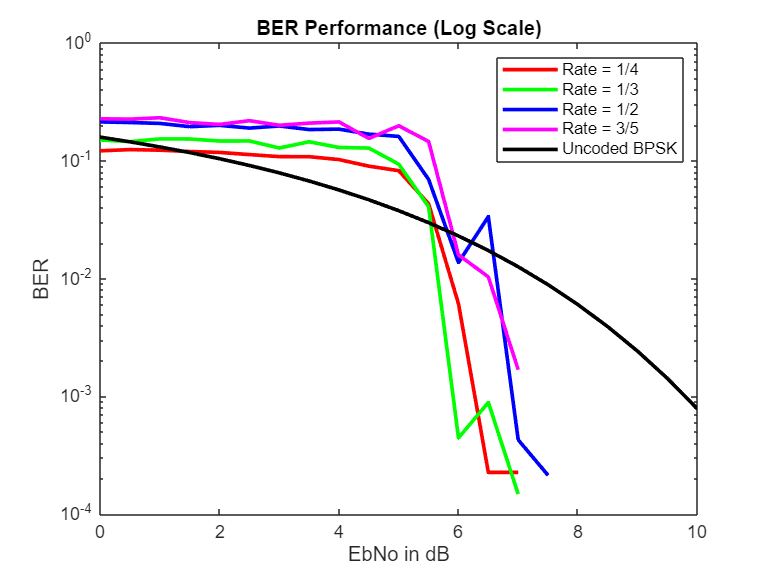

baseGraph5GNR = 'NR_2_6_52'; 
Nsim = 5;
max_itr = 5;
colors = ['r', 'g', 'b', 'm'];


EbNodB = 0:0.5:10;
R = [1/4 1/3 1/2 3/5];

Bit_Error_Rate = zeros(length(R), length(EbNodB));

% Storage for graph Plot of Error Probability vs Eb/No(dB)
p_error = zeros(length(R), length(EbNodB));

% Storage for graph Plot of Success Probabilty vs No of Iteration
p_success_itr = zeros(length(EbNodB), max_itr);

% Index for coderate
coderate_iterator = 1;

for codeRate = R % For base graph NR_2_6_52
    % AWGN Channel

    [B, Hfull, z] = nrldpc_Hmatrix(baseGraph5GNR);
    [mb, nb] = size(B);
    kb = nb - mb;
    kNumInfoBits = kb * z;
    k_pc = kb - 2;
    nbRM = ceil(k_pc / codeRate) + 2;
    nBlockLength = nbRM * z;
    
    H = Hfull(:, 1:nBlockLength);
    nChecksNotPunctured = mb*z - nb*z + nBlockLength;
    H = H(1:nChecksNotPunctured, :);
    
    Nchecks = size(H, 1);

    Rows = size(H, 1);
    Cols = size(H, 2);

    ebno_iterator=1;
    
    for EbNoindex = 1:length(EbNodB)

        EbNo = 10^(EbNodB(EbNoindex) / 10);
        sigma = sqrt(1 / (2 * codeRate * EbNo));
        ErrorinBits = 0;

        for ksim = 1:Nsim
            b = randi([0 1], [kNumInfoBits 1]);
            c = nrldpc_encode(B, z, b');
            c = c(1:nBlockLength)';

            % BPSK Modulation
            s = 1 - 2*c;
           
            received_vector = s + sigma * randn(size(s));
            received_vector = (received_vector < 0);

            M = zeros(Rows, Cols);  % VN to CN messages
            L = zeros(Rows, Cols);  % CN to VN messages
            decoded_msg = zeros(1, Cols);

            % Initialize from VN to CN
            for Col = 1 : Cols
                Connected_CNs = find(H(:, Col));
                for j = 1 : length(Connected_CNs)
                    M(Connected_CNs(j), Col) = received_vector(Col);  % Initial message is received bit
                end
            end

            % Begining decoding iterations
            for itr = 1 : max_itr

                % SPC
                for ir = 1 : Rows
                    Connected_VNs = find(H(ir, :));
                    for j = 1 : length(Connected_VNs)
                        others = M(ir, Connected_VNs([1:j-1, j+1:end]));
                        L(ir, Connected_VNs(j)) = mod(sum(others), 2);  % Parity excluding self
                    end
                end

                % Majority Voting 
                for Col = 1 : Cols
                    Connected_CNs = find(H(:, Col));
                    total_vote = sum(L(Connected_CNs, Col)) + received_vector(Col);
                    decoded_msg(Col) = total_vote > ((length(Connected_CNs) + 1) / 2);

                    for j = 1 : length(Connected_CNs)
                        other_votes = L(Connected_CNs([1:j-1, j+1:end]), Col);
                        count = sum(other_votes) + received_vector(Col);
                        M(Connected_CNs(j), Col) = count > (length(Connected_CNs) / 2);
                    end
                end

                if (isequal(decoded_msg(1:kNumInfoBits), c(1:kNumInfoBits)') && coderate_iterator==2)
                    p_success_itr(ebno_iterator,itr) = p_success_itr(ebno_iterator,itr) + 1;
                end

             end

            % Count bit errors
            bitError = sum(decoded_msg(1:kNumInfoBits) ~= c(1:kNumInfoBits)');
            if(bitError > 0)
                Bit_Error_Rate(coderate_iterator, ebno_iterator) = Bit_Error_Rate(coderate_iterator, ebno_iterator) + bitError;
                p_error(coderate_iterator, ebno_iterator) = p_error(coderate_iterator, ebno_iterator) + 1;
            end
        end
        Bit_Error_Rate(coderate_iterator, ebno_iterator) = Bit_Error_Rate(coderate_iterator, ebno_iterator) / Cols / Nsim;
        p_error(coderate_iterator, ebno_iterator) = p_error(coderate_iterator, ebno_iterator) / Nsim;

        ebno_iterator=ebno_iterator+1;
    end
    coderate_iterator=coderate_iterator+1;
end

p_success_itr = p_success_itr/Nsim;

EbNo = 10 .^ (EbNodB ./ 10);

% Calculate Bit Error Rate (Bit_Error_Rate) for each SNR
ber_uncoded = 0.5 * erfc(sqrt(EbNo ./ 2));

figure;
for idx = 1:length(R)
    semilogy(EbNodB, Bit_Error_Rate(idx, :),'Color', colors(idx), 'LineWidth', 2);
    hold on;
end
semilogy(EbNodB, ber_uncoded,'Color','k', 'LineWidth', 2);
xlabel('EbNo in dB');
ylabel('BER');
title('BER Performance (Log Scale)');
legend('Rate = 1/4', 'Rate = 1/3', 'Rate = 1/2', 'Rate = 3/5','Uncoded BPSK');
hold off;

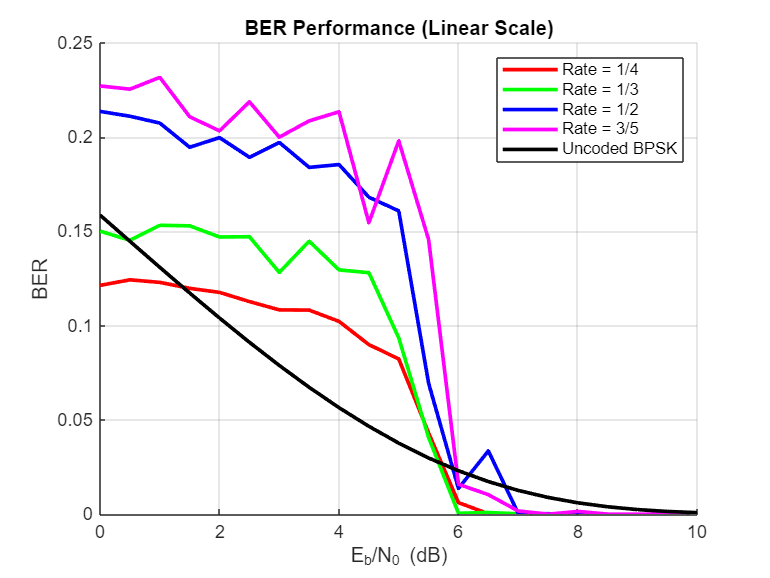


figure;
hold on;
grid on;
for idx = 1:length(R)
    plot(EbNodB, Bit_Error_Rate(idx, :), 'Color', colors(idx), 'LineWidth', 2);
end
plot(EbNodB, ber_uncoded,'Color','k', 'LineWidth', 2);
xlabel('E_b/N_0 (dB)');
ylabel('BER');
title('BER Performance (Linear Scale)');
legend('Rate = 1/4', 'Rate = 1/3', 'Rate = 1/2', 'Rate = 3/5', 'Uncoded BPSK');
hold off;

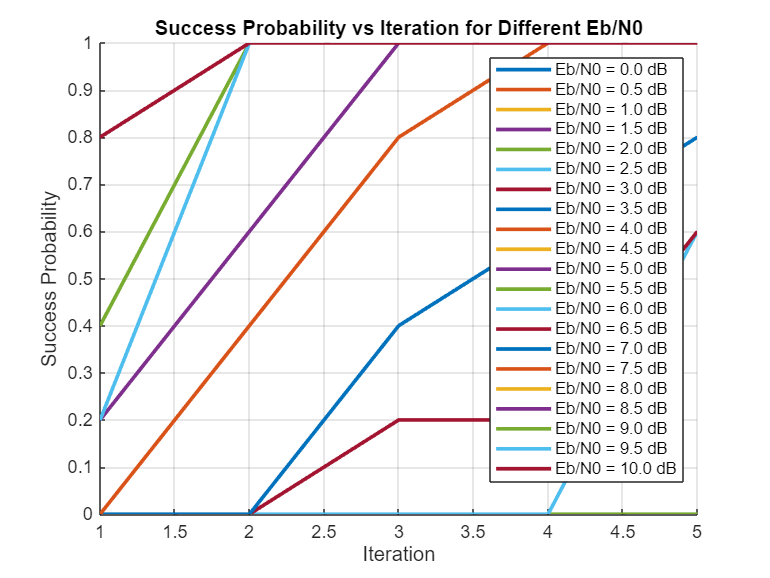


figure;
hold on;
legendEntries = cell(1, length(EbNodB));
for i=1:length(EbNodB)
    plot(1:max_itr,p_success_itr(i,:),'LineWidth',2);
    legendEntries{i} = sprintf('Eb/N0 = %.1f dB', EbNodB(i));
end
xlabel('Iteration');
ylabel('Success Probability');
title('Success Probability vs Iteration for Different Eb/N0');
legend(legendEntries, 'Location', 'northeast');
grid on;
hold off;

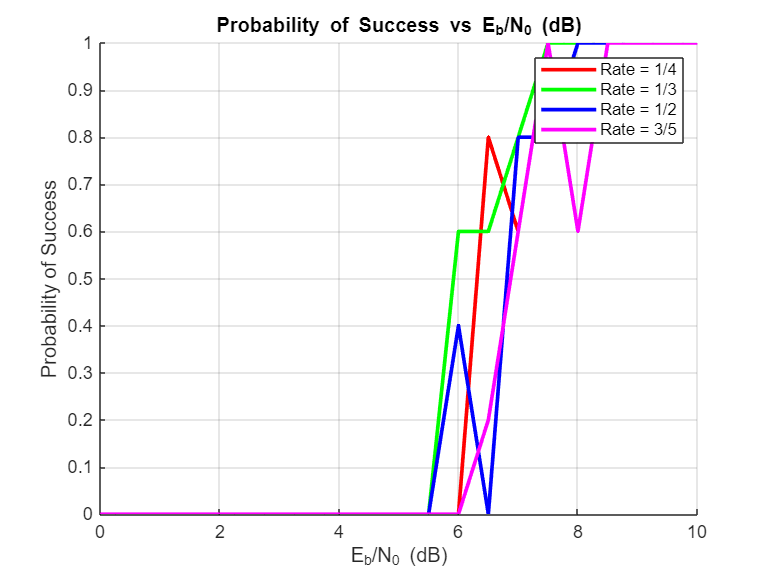


figure;
hold on;
grid on;
for idx = 1:length(R)
    plot(EbNodB, 1-p_error(idx, :), 'Color', colors(idx), 'LineWidth', 2);
end
xlabel('E_b/N_0 (dB)');
ylabel('Probability of Success');
title('Probability of Success vs E_b/N_0 (dB)');
legend('Rate = 1/4', 'Rate = 1/3', 'Rate = 1/2', 'Rate = 3/5');
hold off;

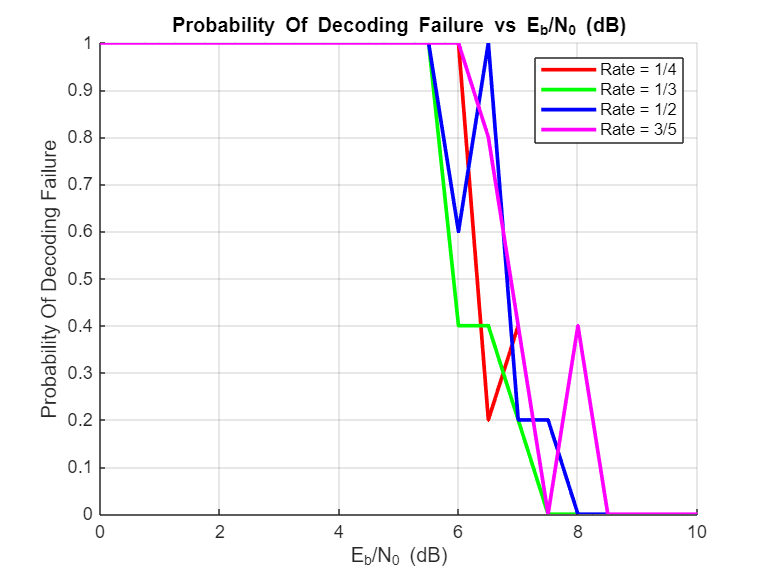


figure;
hold on;
grid on;
for idx = 1:length(R)
    plot(EbNodB, p_error(idx, :), 'Color', colors(idx), 'LineWidth', 2);
end
xlabel('E_b/N_0 (dB)');
ylabel('Probability Of Decoding Failure');
title('Probability Of Decoding Failure vs E_b/N_0 (dB)');
legend('Rate = 1/4', 'Rate = 1/3', 'Rate = 1/2', 'Rate = 3/5');
hold off;